# **RBE500: Foundations of Robotics **

# **Week 7 : Singularity**

**Kathia Coronado**

*Robotics Engineering Graduate Student, Worcester Polytechnic Institute, Worcester, Massachussets, kcoronado@wpi.edu*

## Introduction

The goal of this week's assignment was to learn and practice analyzing real robotic systems for singularites. For this assignment the MECADEMIC real life robot, see figure 1,  was studied and analyzed for singularities. 

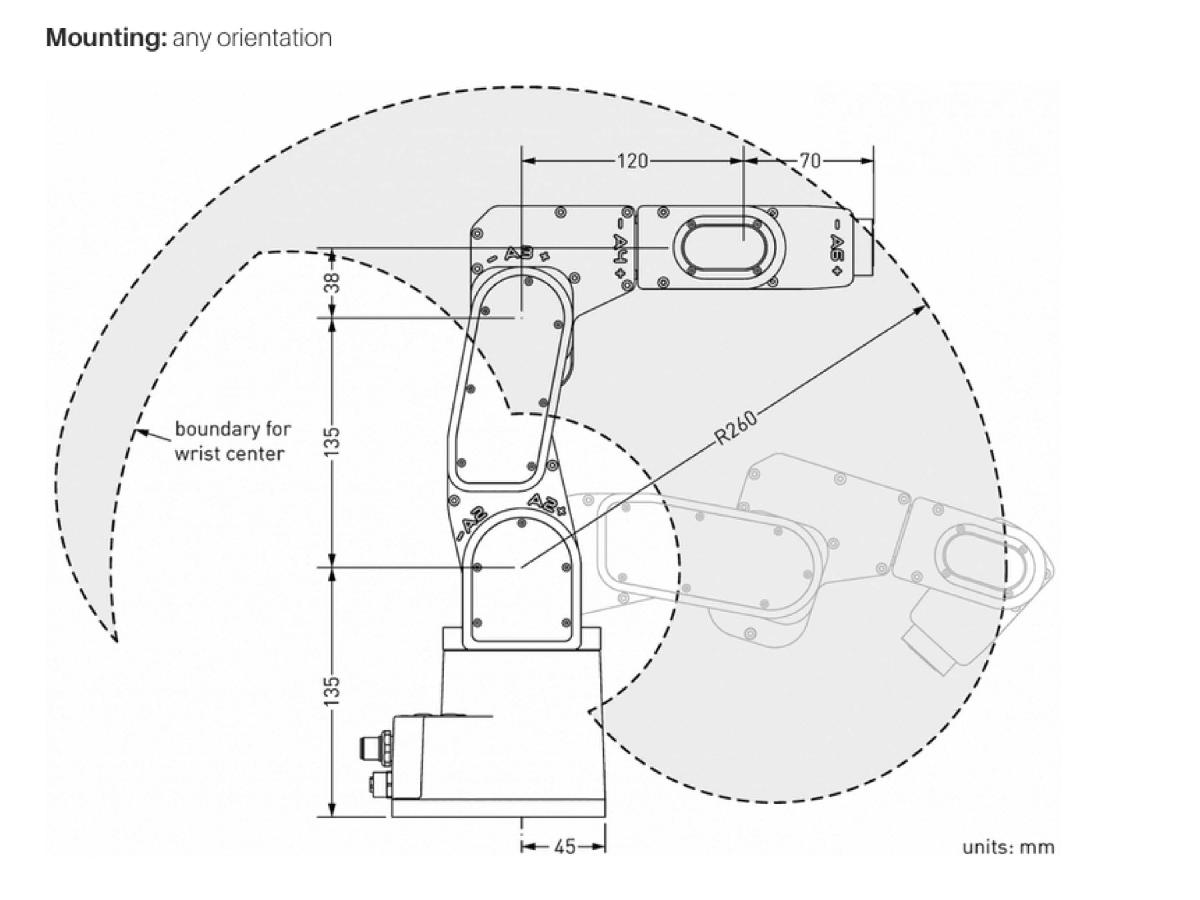

*Figure 1- MECADEMIC robot skemetic*

In order to analyze this system, the DH parameters were calculated for the system in order to get the homogenous transformation matrix (HTM).  Then the jacobian was calculated. THe jacobian was then used to analyze and discover what configurations results in a singularity. 

## Methods and Materials

**Answer :**

`config_1 = [0;0;0;0;0;0]`

`config_2 = [0;47.6813;0;0;0;0]`

`config_3 = [0; -132.3187;0;0;0;0]`

`config_4 =[ 0;0;78.6901;0;0;0]`

 This week's assignment involved analyzing the MECADEMIC robot for singularities, figure 2 display a labeled skematic for the system. This is a 6 degree of freedom (DOF) system, where the 6 joints of the system are revolute.

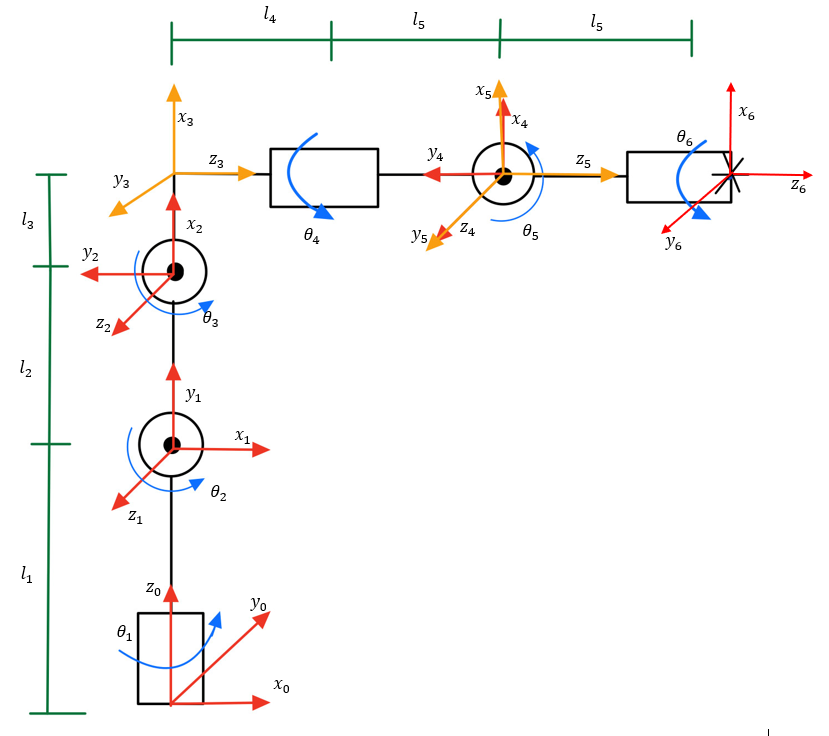

*Figure 2 - Labeled diagram for the MECADEMIC robot *

Singularities are configurations where certain directions of motion might be unattainable. In order to acertain if a particular system has singularities, the jacobian of the matrix must be found. The jacobian is used to determine the rank of the system configuration as well as to determine if the configuration in question is a singular configuration.

To analyze the system transformation matrices of the system must be obtained. For this analysis, the DH method was used to obtain the tranformation matrices. The DH method simplifies the analysis of a multi link manipulator by representing each HTM, $\,A_i$, as a product of four basic tranformations, see equation 3.10.

In order to use the DH method, one must first analyze the system and obtain the link length ($a_i$), link twist ($\alpha_i$), link offset ($d_i$) and joint angle ($\theta_i \,$). For this problem these DH parameters were obtained and displayed on table 1.

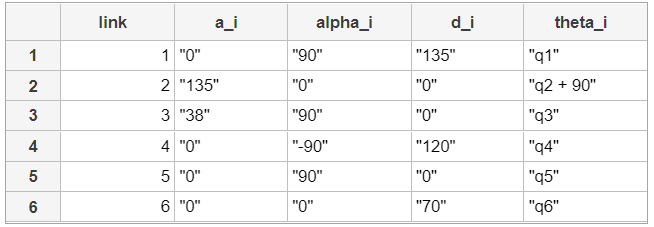

Table 1 -Table 1 - DH parameter of MECADEMIC robot 

Using these parameters equation 3.10, in the textbook can be used to obtain the homogeneous tranformation matrix for each of the links in the system, see equations 1a -d. Substituting the DH parameters in equations, with the appropriate and corresponding link parameters in table 1, the homogeneous transformation matrices for each link in the system can be determined

$H_1^0 =\left\lbrack \begin{array}{cccc}
C\theta_1  & -S\theta_1 C\alpha_1  & S\theta_1 S\alpha_1  & a_1 C\theta_1 \\
S\theta_1  & C\theta_1 C\alpha_1  & -C\theta_1 S\alpha_1  & a_1 S\theta_1 \\
0 & S\alpha_1  & C\alpha_1  & d_1 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                            (1a)

$H_2^1 =\left\lbrack \begin{array}{cccc}
C\theta_2  & -S\theta_2 C\alpha_2  & S\theta_2 S\alpha_2  & a_2 C\theta_2 \\
S\theta_2  & C\theta_2 C\alpha_2  & -C\theta_2 S\alpha_2  & a_2 S\theta_2 \\
0 & S\alpha_2  & C\alpha_2  & d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (1b)

$H_3^2 =\left\lbrack \begin{array}{cccc}
C\theta_3  & -S\theta_3 C\alpha_3  & S\theta_3 S\alpha_3  & a_3 C\theta_3 \\
S\theta_3  & C\theta_3 C\alpha_3  & -C\theta_3 S\alpha_3  & a_3 S\theta_3 \\
0 & S\alpha_3  & C\alpha_3  & d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (1c)

$H_4^3 =\left\lbrack \begin{array}{cccc}
C\theta_4  & -S\theta_4 C\alpha_4  & S\theta_4 S\alpha_4  & a_4 C\theta_4 \\
S\theta_4  & C\theta_4 C\alpha_4  & -C\theta_4 S\alpha_4  & a_4 S\theta_4 \\
0 & S\alpha_4  & C\alpha_4  & d_4 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                            (1d)

$H_5^4 =\left\lbrack \begin{array}{cccc}
C\theta_5  & -S\theta_5 C\alpha_5  & S\theta_2 S\alpha_5  & a_5 C\theta_5 \\
S\theta_5  & C\theta_5 C\alpha_5  & -C\theta_5 S\alpha_5  & a_5 S\theta_5 \\
0 & S\alpha_5  & C\alpha_5  & d_5 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (1e)

$H_6^5 =\left\lbrack \begin{array}{cccc}
C\theta_6  & -S\theta_6 C\alpha_6  & S\theta_6 S\alpha_6  & a_6 C\theta_6 \\
S\theta_6  & C\theta_6 C\alpha_6  & -C\theta_6 S\alpha_6  & a_6 S\theta_6 \\
0 & S\alpha_6  & C\alpha_6  & d_6 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;$                                                                                            (1f)

Using this and some other relationships (such as the order of attachment), the Homogenous transformation matrices were defines for each each joint with respect to the base, see equations,2a - f

$T_1^0 =$$H_1^0$                                                                                                                                                  (2a)

$T_2^0 =H_1^0 H_2^1$                                                                                                                                             (2b)

$T_3^0 =H_1^0 H_2^1 H_3^2$                                                                                                                                        (2c)

$T_4^0 =$$H_1^0 H_2^1 H_3^2 H_4^3$                                                                                                                                    (2d)

$T_5^0 =H_1^0 H_2^1 H_3^2 H_4^3 H_5^4$                                                                                                                                (2e)

$T_6^0 =H_1^0 H_2^1 H_3^2 H_4^3 H_5^4 H_6^5$                                                                                                                             (2f)

The z vectors for each of the HTM can be calculated by multipliing each HTM above by the unit vector z, see equationa 3a-3f. This these terms will be used to calculate the jacobian of each joint. The z vector of the base frame is always just the unit vector.

$z_0 =\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                                                                                                                                   (3a)

$z_1 =H_1^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                                                                                                                              (3b)

$z_2 =H_2^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                                                                                                                              (3c)

$z_3 =H_3^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                                                                                                                              (3d)

$z_4 =H_4^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                                                                                                                              (3e)

$z_5 =H_5^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                                                                                                                              (3f)

$z_5 =H_6^0 \left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack$                                                                                                                                              (3g)

The variable denoted by o is the position vector of the joints HTM. These position vectors can easily be obtained by extracting the last column of the HTM describing the motion of each joint with respect to the base. $o_n$ is the position vector of the end effector, $o_2$ is the position vector of the third joint, $o_1$ is the position vector of the second joint and $o_0$ is the position vector of the first or base joint. eqaution 4a- 4g show this calculation.

$o_n$=$o_6$ = $T_6^0 \left(:,4\right)\;$                                                                                                                                       (4a)

$o_5$ = $T_5^0 \left(:,4\right)\;$                                                                                                                                             (4b)

$o_4$ = $T_4^0 \left(:,4\right)\;$                                                                                                                                             (4c)

$o_3$ = $T_3^0 \left(:,4\right)\;$                                                                                                                                             (4d)

$o_2$ = $T_2^0 \left(:,4\right)$                                                                                                                                              (4e)

$o_1$ = $T_1^0 \left(:,4\right)$                                                                                                                                              (4f)

$o_0$ = $\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \;$                                                                                                                                                 (4g)

Now with these values, the jacobian can be calculated for the system. Jacobian matrices take into account each joint, therefore in order to obtain the jacobian matrix of the system, a jacobian vector for each joint must first be calculated. Equations 5a-5f  were used to obtain the jacobian vector for each joint. $J_1$, $J_2$,  $J_3 ,$ $J_4$ , $J_5$ and $J_6$. These equations use equation 4.81 to calculate the jacobian of each joint, as all of the joints in this assignmnet are revolute joints. The actual values of the jacobian for each joint can be found in the results section, because these matrices were very long and jacobian was not the main focus of the assiment is did not include the actual values in this method section.

$J_1 =\left\lbrack \begin{array}{c}
z_0 \times \left(o_n -o_0 \right)\\
z_0 
\end{array}\right\rbrack$                                                                                                                                   (5a)

$J_2 =\left\lbrack \begin{array}{c}
z_1 \times \left(o_n -o_1 \right)\\
z_1 
\end{array}\right\rbrack$                                                                                                                                   (5b)

$J_3 =\left\lbrack \begin{array}{c}
z_2 \times \left(o_n -o_2 \right)\\
z_2 
\end{array}\right\rbrack$                                                                                                                                   (5c)

$J_4 =\left\lbrack \begin{array}{c}
z_3 \times \left(o_n -o_3 \right)\\
z_3 
\end{array}\right\rbrack$                                                                                                                                   (5d)

$J_5 =\left\lbrack \begin{array}{c}
z_4 \times \left(o_n -o_4 \right)\\
z_4 
\end{array}\right\rbrack$                                                                                                                                   (5e)

$J_6 =\left\lbrack \begin{array}{c}
z_5 \times \left(o_n -o_5 \right)\\
z_5 
\end{array}\right\rbrack$                                                                                                                                   (5f)

Now equations 5a-5f can be completed by inputing the corresponding equations from 2, 3 and equations 4.  Once the jacobian vectors are obtained, the the entire jacobian matrix of the system can be obtained by coming combining the vectors, see equations 6. the actual result of this calculated was omited from this method section as it was very long, the result can be found in the result section of this report. 

$J=J_1 J_2 J_3 J_4 J_5 J_6$                                                                                                                                            (6)

Now that the jacobian matrix for the system, the singularity analysis can begin. The first part of this calculated involved decoupling the jacobian matrix. The goal is to section off sections of the jacobian in order to, make the calculation less computationally extensive. The method used to section off the jacobian is illustrated by equation 4.91 in the Robot Modeling and Control textbook. Equations 7 and 8 show the decoupling of J, the jacobian,  into $J_{11}$ and $J_{22}$. The section $J_{11}$is the upper left section of the jacobian and it is useful for calculating arm singularities.The section $J_{22}$ is the lower right part of the jacobian and it is useful for calculating wrist singularities.

 $J_{11} =J\left(1:3,1:3\right)$                                                                                                                                       (7)

$J_{22} =J\left(4:6,4:6\right)$                                                                                                                                        (8)

With these two sections of the jacobian, the determinant of of each section can be determined and multiplying these two determinants, the determinent of the jacobian can be calculated, using equation 4.95  in the textbook. 

Singularities can be found by solving for the joint variables when the determinent of the jacobian matrix is equal 0, see equation 4.90. In order to solve this, I used the matlab solve function for the configurations where the determinent of the Jacobian is 0. Equation 9 shows the matlab command that i used to find all of the singular configurations. Using this command I learned that the system has four singular configurations.

theta_val_at_sing = solve (det(J), [q1 q2 q3 q4 q5 q6])                                                                                  (9)

To find out which of the configurations is a wrist singularity, I solved for the determinent of $J_{22}$, see equation 10. Using this equation, I found out that there is only 1 singuar wrist configuration and I was able to determine what the configuration is. 

theta_at_wrist_sing = solve (det(J22), [q1 q2 q3 q4 q5 q6])                                                                          sss(10)

To solve for the arm singularities I used the determinent of $J_{11}$, see equation 11. Using this equation is was able to find out that there are three arm configurations and  determine what those configurations were. The elbow singularitty configuration is the last configuration returned from this list.

## Results

To calcualte the singularitites of the system, the jacobian and HTm for the system must be calculated. herefore the first fordward kinematic analysis must be done to the system.

In the code exerpt below, I first define my symbolic variables. 

q1, q2, q3, q4, q5and q6 are the joint variables. and l1, l2, l3, l4 and l5 are the link lengths

clear;clc;
syms  q1 q2 q3 q4 q5 q6
l1 = 135;
l2 = 135;
l3 = 38;
l4 = 120;
l5 = 70;

In order to use the DH method, one must first analyze the system and obtain the link length ($a_i$), link twist ($\alpha_i$), link offset ($d_i$) and joint angle ($\theta_i \,$). For this problem these DH parameters were obtained and displayed on the table below.


a = [0; l2; l3; 0; 0; 0];
alpha = [90; 0; 90; -90; 90; 0];
d = [l1; 0; 0; l4; 0; l5];
theta = [q1; q2+90; q3; q4; q5; q6];
n_links = length(theta);
DH_tab = DH_table(n_links,a , alpha, d, theta) % TABLE 

DH_tab = 6×5 table
    link     a_i     alpha_i     d_i      theta_i 
    ____    _____    _______    _____    _________

     1      "0"       "90"      "135"    "q1"     
     2      "135"     "0"       "0"      "q2 + 90"
     3      "38"      "90"      "0"      "q3"     
     4      "0"       "-90"     "120"    "q4"     
     5      "0"       "90"      "0"      "q5"     
     6      "0"       "0"       "70"     "q6"     


Call out function that uses DH parameters to find the homogeneous transformation matrix using the the DH method. A is a cell array that holds all of the  sequential HTM for the system

%%%% get HTM functions with DH in degrees
%%{
A = GetDH(a, alpha, d, theta);  

Using these sequetial HTMs calcualted above, the HTM for each frame with respect to the base frame can be calculated. To obtain these HTMs, the sequential HTMs must be postmultiplied in order, from the base to the target frame.

T01 = simplify(A{1});
T02 = simplify(A{1}*A{2});
T03 = simplify(A{1}*A{2}*A{3});
T04 = simplify(A{1}*A{2}*A{3}*A{4});
T05 = simplify(A{1}*A{2}*A{3}*A{4}*A{5});
T06 = simplify(A{1}*A{2}*A{3}*A{4}*A{5}*A{6});
%%}
%%%% get HTM functions with DH in radians
%{
Ar = GetDHrad(a, alpha, d, theta);  
T01r = simplify(Ar{1});
T02r = simplify(Ar{1}*Ar{2});
T03r = simplify(Ar{1}*Ar{2}*Ar{3});
T04r = simplify(Ar{1}*Ar{2}*Ar{3}*Ar{4});
T05r = simplify(Ar{1}*Ar{2}*Ar{3}*Ar{4}*Ar{5});
T06r = simplify(Ar{1}*Ar{2}*Ar{3}*Ar{4}*Ar{5}*Ar{6});
%}
Ts={T01 T02 T03 T04 T05 T06};

Now that the forward kinematics of the system was calculated and the transformation matrices from each frame to the base frame, the jacobian analysis can now be begin.

In order to speed up the problem solving time for this exam and ensure that I have sufficient time to complete it, I have created a function that calculates the jacobian matrix of a system:

geojac(Ts,theta)

The inputs of the function are :

**Ts :** the list of all of the HTM  the respresent the tranformation of each frame to the base frame. For this problem that is (H01, H02, H03, H04)

**theta:** an array that binarily discerns if the joint is prismatic or revolute. This is done by checking if any of the values are 0. If the values is 0 then that joint is prismatic, if the values is non zero then the joint is revolute. The theta dh parameter list can be used as input.

Here i am calling the function that calculates the jacobian of the system, geojac. 

The output of the function is the total Jacobian function, that combines J1 through J4 for this system.0

%Tsr = {T01r T02r T03r T04r T05r T06r};
J = simplify(geojac(Ts, theta))

revolute
revolute
revolute
revolute
revolute
revolute


%J = simplify(geojac(Tsr, theta))

Here I decouple the jacobian matrix, j into J11 and J22, per equation 4.91

% decoupling 
% 3x3 blocks of jacobian
J11 = simplify(J(1:3,1:3));
J22 = simplify(J(4:6,4:6));

Here I calculate the determinent for the two sections and then use those sections to calculate the jacobian's determinent, using equation 4.95. This simplifies the calculation .


% determinant calculation 
detJ11= simplify(det(J11));
detJ22= simplify(det(J22));
detJ = simplify(detJ11*detJ22)

Calculation of the Wrist singularity :

Here i set a linspace array for each of the joint variables 

% wrist singularity
% there is only 1 singular wrist config
th1 =linspace(0,360,45);
th2 =linspace(0,360,45);
th3 =linspace(-90,90,45);
th4 =linspace(0,360,45);
th5 =linspace(0,360,45);
th6 =linspace(0,360,45);

Here I use matlab solver to solve for the configuration where the determinent of J22 is 0. Using J22 solves for wrist singularities. The result of this calculation let me know that there is only one wrist singularity configuration.

theta_at_wrist_sing = solve (detJ22, [q1 q2 q3 q4 q5 q6]) 

theta_at_wrist_sing = struct with fields:
    q1: [1×1 sym]
    q2: [1×1 sym]
    q3: [1×1 sym]
    q4: [1×1 sym]
    q5: [1×1 sym]
    q6: [1×1 sym]


Here I index the variables for the wrist singularity configuration that I calculatted. 

wirst_config_1 = double([theta_at_wrist_sing .q1(1);
theta_at_wrist_sing .q2(1);
theta_at_wrist_sing .q3(1);
theta_at_wrist_sing .q4(1);
theta_at_wrist_sing .q5(1);
theta_at_wrist_sing .q6(1)])

wirst_config_1 =      0
     0
     0
     0
     0
     0


In order to analyze the wrist singularity, I plot the Determinent of J22 against the Joint angle 5, which is the cause of the singularity.   I substituted the joint values into the equation for plotting. 

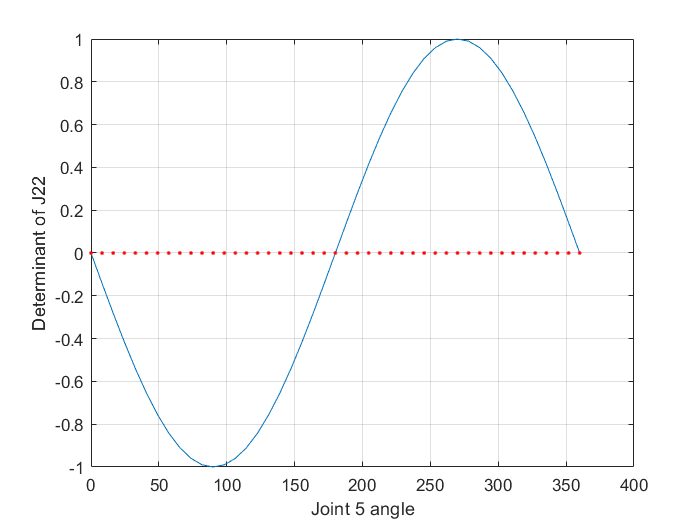

wrist_subs= subs(detJ22,{q5},{th5});
plot(th5,wrist_subs)
hold on 
plot(th5,0, '-r.')
hold off 
grid on 
xlabel('Joint 5 angle')
ylabel('Determinant of J22')

Calculation of Elbow Singularity:

In this section i set a linspace array for each of the joint variables. I set this range in order to analyze the elbow singularity in a plot.

th1 =linspace(0,0,45);
th2 =linspace(0,0,45);
th3 =linspace(-80,80,45);
th4 =linspace(0,0,45);
th5 =linspace(0,0,45);
th6 =linspace(0,0,45);

Here I use matlab solver to solve for the configuration where the determinent of J11 is 0. Using J11 solves for arm singularities. The result of this calculation let me know that there is 3 arm singularities singularity configuration. Then I substituted the joint values into the equation for plotting. 

elbow_sing = solve (detJ11, [q1 q2 q3 q4 q5 q6]) 

elbow_sing = struct with fields:
    q1: [3×1 sym]
    q2: [3×1 sym]
    q3: [3×1 sym]
    q4: [3×1 sym]
    q5: [3×1 sym]
    q6: [3×1 sym]


elbow_subs= subs(detJ11,{q1 q2 q3 q4 q5 q6}, {th1 th2 th3 th4 th5 th6});

To analyze these configurations, I plotted the determinent of J11 vs joint angle 3

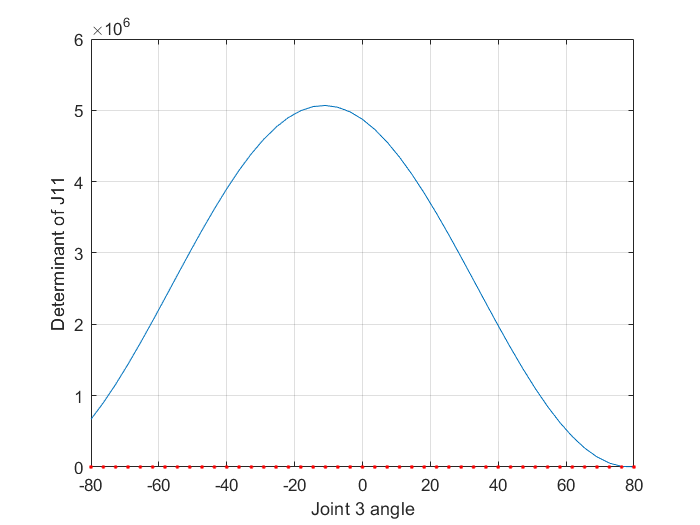

plot(th3,elbow_subs)
hold on 
plot(th3,0, '-r.')
hold off 
grid on 
xlabel('Joint 3 angle')
ylabel('Determinant of J11')

Calculation of Shoulder singularity:

In this section i set a linspace array for each of the joint variables. I set this range in order to analyze the shoulder singularity in a plot.

th1 =linspace(0,180,45);
th2 =linspace(0,180,45);
th3 =linspace(0,180,45);
th4 =linspace(0,180,45);
th5 =linspace(0,180,45);
th6 =linspace(0,180,45);

Then I substituted the joint values into the equation for plotting. 

shoulder_subs= subs(detJ11,{q1 q2 q3 q4 q5 q6}, {th1 th2 th3 th4 th5 th6});


To analyze these configurations, I plotted the determinent of J vs joint angle 5

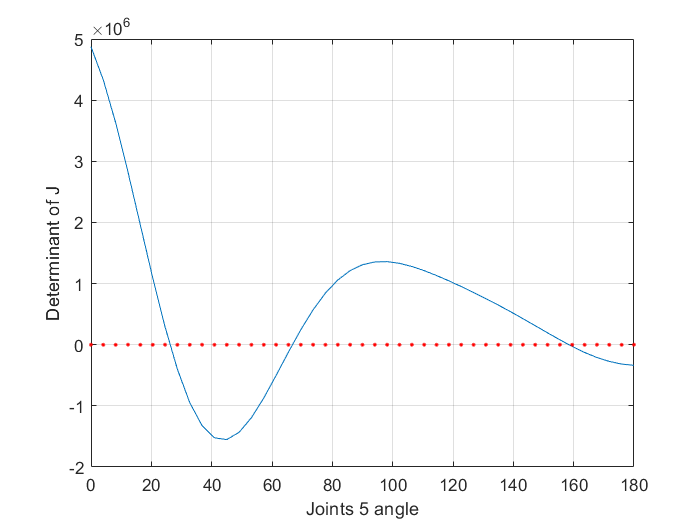

plot(th5,shoulder_subs)
hold on 
plot(th5,0, '-r.')
hold off 
grid on 
xlabel('Joints 5 angle')
ylabel('Determinant of J')

Here, I solve for all of the singular configurations in one sweep. I set the determinent of J equal to 0, and then use matlab solver to obtain the singular configurations 

% solve for theta values 
% there are 4 singular configurations 
theta_val_at_sing = solve (detJ, [q1 q2 q3 q4 q5 q6])

theta_val_at_sing = struct with fields:
    q1: [4×1 sym]
    q2: [4×1 sym]
    q3: [4×1 sym]
    q4: [4×1 sym]
    q5: [4×1 sym]
    q6: [4×1 sym]


Here I index all of the configurations in order to get the actual degrees that each joint variable is in order to obtain the singularity. 

config_1 = double([theta_val_at_sing.q1(1);
theta_val_at_sing.q2(1);
theta_val_at_sing.q3(1);
theta_val_at_sing.q4(1);
theta_val_at_sing.q5(1);
theta_val_at_sing.q6(1)])

config_1 =      0
     0
     0
     0
     0
     0




%shoulder singularity
config_2 = double([theta_val_at_sing.q1(2);
theta_val_at_sing.q2(2);
theta_val_at_sing.q3(2);
theta_val_at_sing.q4(2);
theta_val_at_sing.q5(2);
theta_val_at_sing.q6(2)])

config_2 =          0
   47.6813
         0
         0
         0
         0



config_3 = double([theta_val_at_sing.q1(3);
theta_val_at_sing.q2(3);
theta_val_at_sing.q3(3);
theta_val_at_sing.q4(3);
theta_val_at_sing.q5(3);
theta_val_at_sing.q6(3)])

config_3 =          0
 -132.3187
         0
         0
         0
         0



% elbow singularity
config_4 = real(double([theta_val_at_sing.q1(4);
theta_val_at_sing.q2(4);
theta_val_at_sing.q3(4);
theta_val_at_sing.q4(4);
theta_val_at_sing.q5(4);
theta_val_at_sing.q6(4)]))

config_4 =          0
         0
   78.6901
         0
         0
         0


ans = 3

ans = 3

ans = 3

ans = 3

### Functions

#### geojac: The Jacobian function 

This function calculates the jacobian of any system. The inputs of this function are the transformation matrices of all of all the joints with respect to the bas frame and the theta list from DH parameters. the outputs of this function is  the jacobian matrix. This function also outputs which type of joints were assumed for each jacobian vector

function jaco= geojac(Ts, theta)

o ={}; % will hold position vectors 
z={}; % will hold z vector 
j={}; % will hold all of the jacobians

The variable denoted by o is the position vector of the joints HTM. These position vectors can easily be obtained by extracting the last column of the HTM describing the motion of each joint with respect to the base. 

the variable denoted by z is a unit vector along the direction of motion. This can be obtain by premultipliying the z unit vector [0;0;1] by the rotation matrix of the system.

First define the postion vector( o0) and unit z vector(z0) of frame zero. These two will never change. 

o0: is at the base of the robot or  the origina so its location is zero

z0: is the z vector for the base of the robot, this unit vector is always [0;0,1] as it is the 0 unit vector and does not require transformations with respect to the 0 coordinate frame

o{1}= [0; 0; 0]; % o0
z{1} = [0;0;1]; % z0

Loop through all of the transformation matrices ( from each frame to the base frame) and calculate each position vector and unit z vector.

 The position vectors, o, can easily be obtained by extracting the last column of the HTM describing the motion of each joint with respect to the base. 

The z unit vectors, z, can be be obtain by premultipliying the z unit vector [0;0;1] by the rotation matrix of the system.

for  i = (1: length(Ts))
    o{i+1} = expand(Ts{i}(1:3,4));
    z{i+1} = Ts{i}(1:3,1:3)*[0;0;1];

end

Now that we have all of the variables associates with equations 4.81  ( jacobian equation for revolute joitns) and 4.82 ( jacobian equation for prismatic joints), the jacobian vector can be calculated for each joint.

In order to discern which equation to use to calculate jacobian the variable theta is used. 

If  theta is 0, then the joint is prismatic and equation 4.82 can be used

if theta is not 0, then the joint is revolute and equation 4.81 can be used 

jac = [];
for  k = (1: length(Ts))
    if theta(k) == 0 
        display('prismatic')
        ji = [z{k};0;0;0];  
    else 
        display('revolute')
        ji = [cross(z{k},(o{length(Ts)+1}-o{k}));z{k}]; 
    end  
    j{k} = ji;
    

I then combined all of the jocabian vectors from J1 to Jn into a full jacobian matrix.

    jac =[jac ji];
end

jaco=simplify(jac);

end

#### DH_table: DH table display function

Function to create DH table for display

This function plots the position of the end effector given the HTM, the symbolic variables and the the values you want to sub in

function [T] = DH_table(n_links, a_i, alpha_i, d_i, theta_i)
% Author: Brian Evarts
% Function to create DH table for display
% Returns: A DH Table with strings as values for IMRD display puroses
    link = linspace(1,n_links, n_links)';   
    a_i_str = string(a_i);
    alpha_i = string(alpha_i);
    d_i_str = string(d_i);
    theta_i_str = string(theta_i);
    T = table(link, a_i_str,alpha_i, d_i_str,theta_i_str, 'VariableNames', {'link','a_i', 'alpha_i' 'd_i', 'theta_i'});
    
end 

#### plotee: Plotting end effector function

This function plots the position of the end effector given the HTM, the symbolic variables and the the values you want to sub in

function plotee(T,q,qt)
x = eval(subs(T(1,4),q,qt));
y = eval(subs(T(2,4),q,qt));
z = eval(subs(T(3,4),q,qt));
plot3(x,y,z)
grid on
xlabel('X ')
ylabel('Y ')
zlabel('Z (mm)')
end

This function uses the DH parameter to calculated the HTM using the DH method. This function will work for any number of joints. The output of this function is a cell array

function [x_line, y_line, z_line] = draw_coordinate_axis(transform, length, x_color, y_color, z_color)    
%Author: Kieth Chester
%Date: 3/1/2021
    origin = transform * [0; 0; 0; 1;];
    x = transform * [length; 0;         0;      1; ];
    y = transform * [0;      length;    0;      1; ];
    z = transform * [0;      0;         length; 1; ];
    x_line = line('XData', [origin(1) x(1)], 'YData', [origin(2) x(2)], 'ZData', [origin(3) x(3)], 'Color', x_color, 'LineWidth', 3);
    y_line = line('XData', [origin(1) y(1)], 'YData', [origin(2) y(2)], 'ZData', [origin(3) y(3)], 'Color', y_color, 'LineWidth', 3);
    z_line = line('XData', [origin(1) z(1)], 'YData', [origin(2) z(2)], 'ZData', [origin(3) z(3)], 'Color', z_color, 'LineWidth', 3);
end

#### GetDH: Function that calculates HTM using DH parameters (degrees)

This function uses the DH parameter to calculated the HTM using the DH method. This function will work for any number of joints. The output of this function is a cell array

function A = GetDH (a, alpha,d,theta)
A = {};
for i = (1:length(a))
    
    H = [ cosd(theta(i)) -sind(theta(i))*cosd(alpha(i)) sind(theta(i))*sind(alpha(i)) a(i)*cosd(theta(i));
         sind(theta(i)) cosd(theta(i))*cosd(alpha(i)) -cosd(theta(i))*sind(alpha(i)) a(i)*sind(theta(i));
         0 sind(alpha(i)) cosd(alpha(i)) d(i);
         0 0 0 1];
    A{i}= simplify((H));
end
end

#### GetDHrad: Function that calculates HTM using DH parameters (radians)

function A = GetDHrad (a, alpha,d,theta)
A = {};
theta = theta*180/pi;
for i = (1:length(a))
    
    H = [ cosd(theta(i)) -sind(theta(i))*cosd(alpha(i)) sind(theta(i))*sind(alpha(i)) a(i)*cosd(theta(i));
         sind(theta(i)) cosd(theta(i))*cosd(alpha(i)) -cosd(theta(i))*sind(alpha(i)) a(i)*sind(theta(i));
         0 sind(alpha(i)) cosd(alpha(i)) d(i);
         0 0 0 1];
    A{i}= simplify((H));
end
end

## Discussion

This weeks assignment involved calculating and analyzing the singularities involved with the MECADEMIC robot. In order to calculate the singularities I first needed to do the forward kinematics of the system (FK) in order to obtain the HTMs of the joints and then use that to obtain the jacobian. Once the jacobian matrix was symbolically calculated, the singularity configurations could be solved for by setting the determinent of the jacobian to 0.  In order to discern the types of singularities in the system, the jacobian decoupled sections could be used. Using this method I was able to discern the wrist singularity from the arm singularity. To better visualize this solution, made three plots of the determinent of the jacobian sections vs the joint that caused the singularity. 

The first plot of the assignmnet showed the singular  wrist configuration, I found that the wrist singularity happened when all of the angles were 0, this was confirmed by the plot. The plot shows that the determinent of J22 became zeros when joint 5 was 0, 180 and 360 degrees.  The second plot, was an attempt at better vizualizing the elbow singularity, I am still confused about the elbow singularity, but I was able to obtain a configuration for when the elbow singularity occurs. The plot shows that the elbow singularity occurs when joint 3 has an angle of about 78, this is confirmed with my configuration calculation. This was not the value that I was expecting as the problem statement asked to prove that the singularity occurs at around -72 degrees.  The third plot displays the shoulder singularities and it also confirms what my configuration calculation was. The shoulder singularities occur when joint 2 is about 47 degrees, when joint 2 is about -132 and when joint 3 equals about 78 degrees. 

All in all, this weeks assignment was interesting and challenging. It was interesting to learn how to decouple a jacobian matrix in order to simplify computation. Also it was satisfying to learn and validate the singularities of a real system. This week's assignment was challenging in that this was a 6DOF robot, so the math involved with the system was more complex than the previous work we have done before, especially the DH parameters . Also during my calculation, my matlab kept crashing while trying to solve for the determinent of the jacobian matrix of the system, so that was a bit fustrating and involved alot of analysis and rethinking of the methods and choices I made while trying to solve this problem. However Once I redited my DH parameters and made sure to decouple the jacobian, it was able to obtain results. 

## References

(1) Spong et al. (2020).* Robot Modeling and Control *(2nd Edition). Wiley.